## Schrenk Approximation for Spanwise Wing Loading

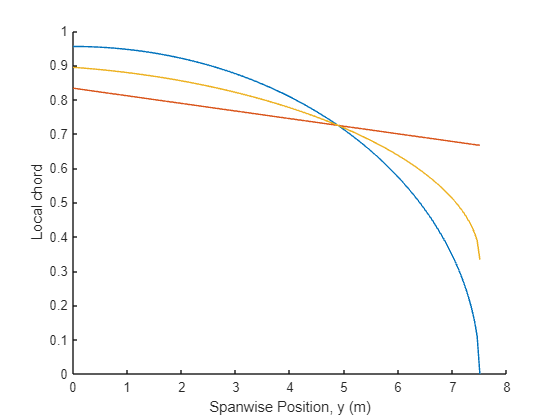

clear;
clc;
close all;

%% INPUTS

AR = 20;
e = 0.85;
b = 15 ;              % Wing span [m]
S = 11.25 ;           % Wing area [m^2]
lambda = 0.8 ;        % Taper ratio, ct/cr

x_CG = 0.35 * (S/b);   % CG position
x_C = 0.25 * (S/b);  % AC posithin

CD_0 = (0.012 + 0.015)/2;

roh = 1.225;
V = 22;

mass = 280 ;          % Aircraft mass [kg]
g = 9.81;            % Gravitational acceleration [m/s^2]

K = 1 / ( pi * e * AR);

WLF = 3.80;  %% wing loading factor

n = 150 ; %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Spanwise positions
y = linspace(0, b/2, n);


c_eleptical = (4*S/(pi*b)).*sqrt(1-(2*y/b).^2);

c_actual = 2*S/((1+lambda)*b).*(1-(2*y/b*(1-lambda)));

cCla = 0.5*(c_actual+c_eleptical);

figure
hold on

plot(y,c_eleptical)
plot(y,c_actual)
plot(y,cCla)
xlabel('Spanwise Position, y (m)')
ylabel('Local chord')

hold off

## Lift distribution

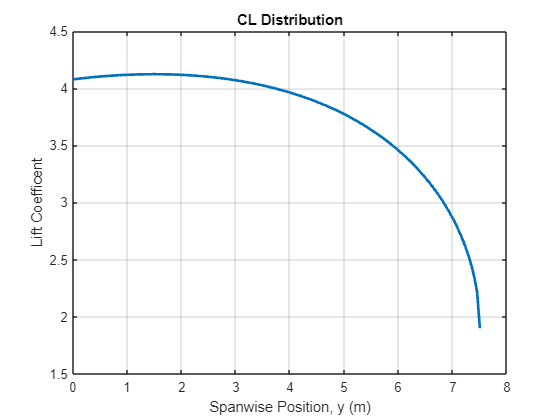

CL = (cCla./c_actual) * WLF;
Lift = 0.5 * roh * V^2 *S .*CL;

figure;
plot(y,CL,'LineWidth',2)

grid on
box on

xlabel('Spanwise Position, y (m)')
ylabel('Lift Coefficent')
title('CL Distribution')

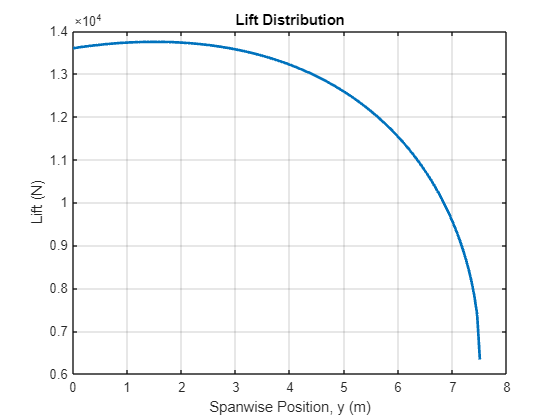


figure;
plot(y,Lift,'LineWidth',2)
grid on
box on

xlabel('Spanwise Position, y (m)')
ylabel('Lift (N)')
title('Lift Distribution')

delta_y = y(2) - y(1);
avg_c_element = zeros(1,n);

for i = 1:n-1

    c1 = c_actual(i);
    c2 = c_actual(i+1);
    avg_c_element(i) = 0.5*(c1 + c2);
end

element_area = zeros(1,n);
for i = 1:n-1
    element_area(i) = delta_y * avg_c_element(i) ;
end

avg_local_element_Cl = zeros(1,n);
for i = 1:n-1
    avg_local_element_Cl(i) = 0.5.*(CL(i) + CL(i+1)) ;
end

element_lift = zeros(1,n);
for i = 1:n-1
    element_lift(i) = 0.5 * roh * V^2 *element_area(i) .*avg_local_element_Cl(i);
end

## Shear Force Sx ( from lift)

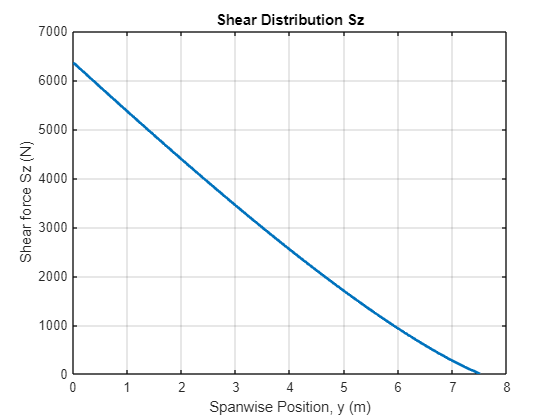

shear_force_z = flip(cumsum(flip(element_lift)));

y_mid = [0, (y(1:end-1) + y(2:end))/2, b/2];

Sz_plot = [sum(element_lift), shear_force_z];

figure;
plot(y_mid,Sz_plot,'LineWidth',2)
grid on
box on

xlabel('Spanwise Position, y (m)')
ylabel('Shear force Sz (N)')
title('Shear Distribution Sz')

## Bending Moment Mx (from lift)

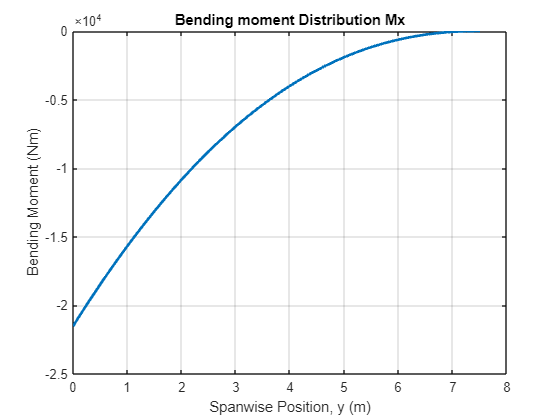

Mx = flip(cumtrapz(flip(y), flip(shear_force_z)));
figure;
plot(y,Mx,'LineWidth',2)
grid on
box on

xlabel('Spanwise Position, y (m)')
ylabel('Bending Moment (Nm)')
title('Bending moment Distribution Mx')

## Drag distribution

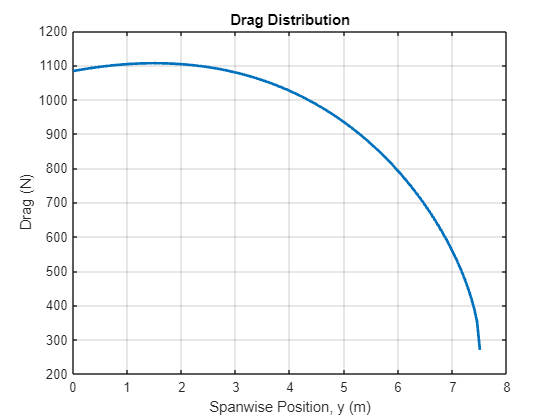

CD = CD_0 + K.*CL.^2 ;
Drag = 0.5 * roh * V^2 *S .*CD;

figure;
plot(y,Drag,'LineWidth',2)
grid on
box on

xlabel('Spanwise Position, y (m)')
ylabel('Drag (N)')
title('Drag Distribution')

avg_local_element_Cd = zeros(1,n);
for i = 1:n-1
    avg_local_element_Cd(i) = 0.5.*(CD(i) + CD(i+1)); 
end

element_drag = zeros(1,n);
for i = 1:n
    element_drag(i) = 0.5 * roh * V^2 *element_area(i) .*avg_local_element_Cd(i);
end

## Shear Force Sx (from drag)

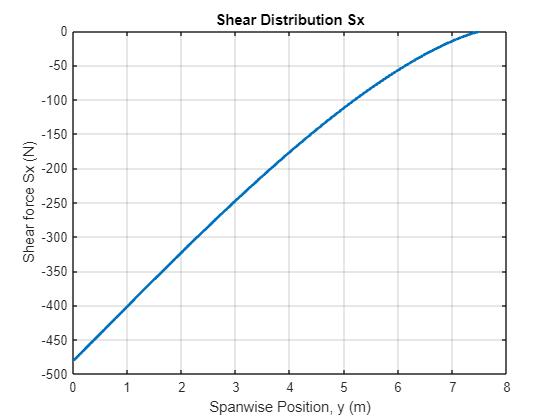

shear_force_x = -flip(cumsum(flip(element_drag)));

Sx_plot = [-sum(element_drag), shear_force_x];

figure;
plot(y_mid,Sx_plot,'LineWidth',2)
grid on
box on


xlabel('Spanwise Position, y (m)')
ylabel('Shear force Sx (N)')
title('Shear Distribution Sx')

## Bending Moment Mz (from drag)

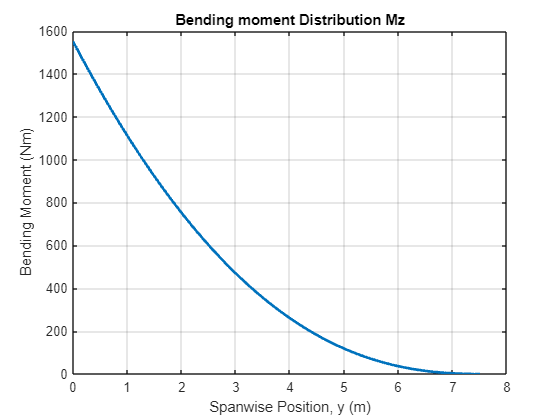

Mz = flip(cumtrapz(flip(y), flip(shear_force_x)));
figure;
plot(y,Mz,'LineWidth',2)
grid on
box on

xlabel('Spanwise Position, y (m)')
ylabel('Bending Moment (Nm)')
title('Bending moment Distribution Mz')

## Bending Moment My (from airfoil pitching moment , lift and drag)

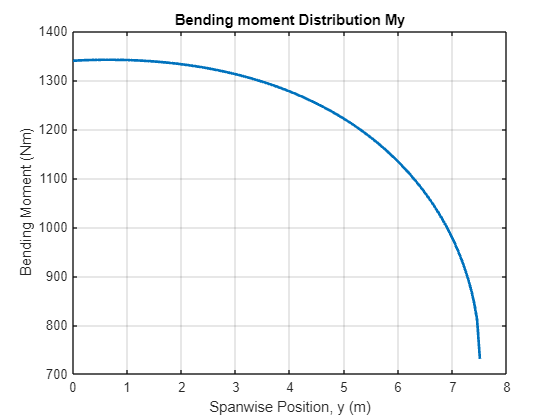

Cm = 0.114960299 ;

My = zeros(1,n);

for i = 1:n 
    My(i) =  (0.5 * roh * V^2 *S*Cm.*c_actual(i)) + (x_CG - x_C)*Lift(i) + 0 * Drag(i);
end


figure;
plot(y,My,'LineWidth',2)


grid on
box on

xlabel('Spanwise Position, y (m)')
ylabel('Bending Moment (Nm)')
title('Bending moment Distribution My')

## Data for selected sections


%for root section
Sx_r = Sx_plot(1)

Sx_r = -479.4714

Sy_r = 0

Sy_r = 0

Sz_r = Sz_plot(1)

Sz_r = 6.3360e+03

Mx_r = Mx(1)

Mx_r = -2.1521e+04

My_r = My(1)

My_r = 1.3393e+03

Mz_r = Mz(1)

Mz_r = 1.5516e+03